# PascoGeigerAttenuationAnalysis

Fit results of PascoGeigerAudioAnalysis to find attenuation length for Co-60 in Pb.

Author: D. Carlsmith

### Enter data by hand for Geiger counter rate and attenuator thickness

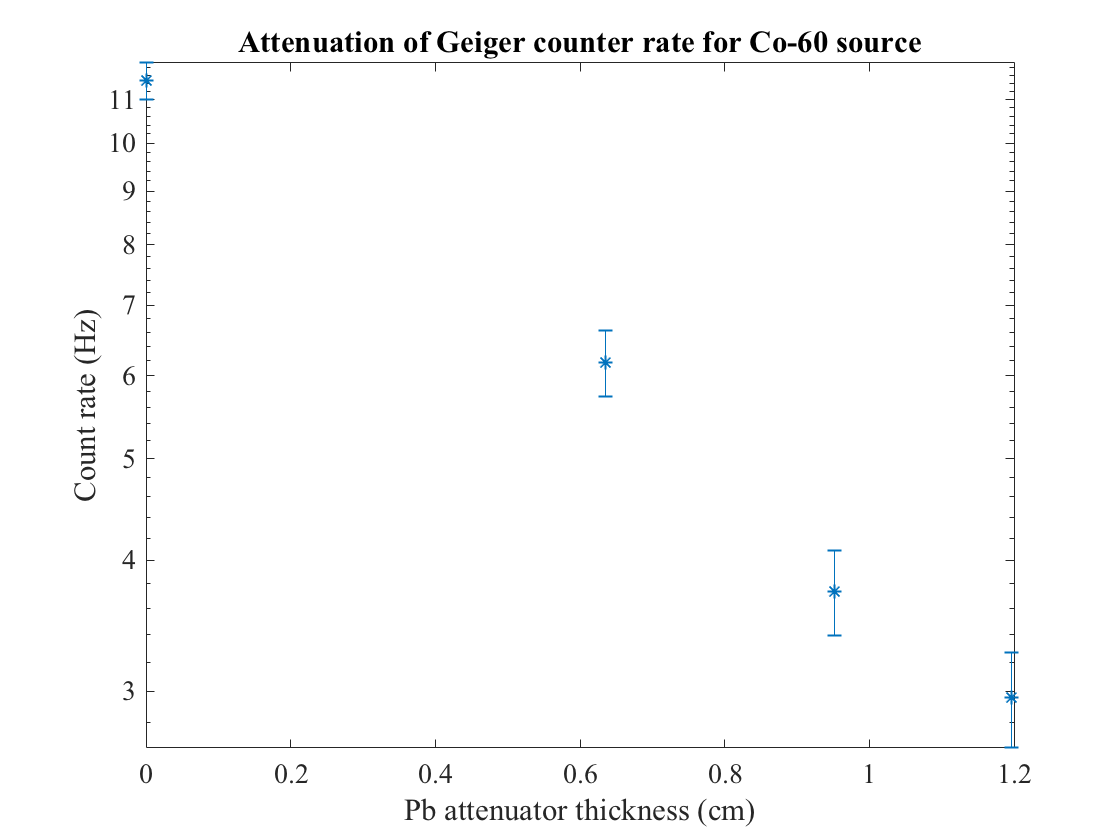

x=[0.000,0.250,0.375,0.471]*2.54; % Pb thickness inches=>cm
rate = [11.46,6.18, 3.74,2.96]; %Hz
rateerr=[0.46,0.45,0.35,0.31];
errorbar(lenPb,rate,rateerr,'*')
set(gca,'YScale','log')
title('Attenuation of Geiger counter rate for Co-60 source')
xlabel('Pb attenuator thickness (cm)');ylabel('Count rate (Hz)')

### Fit the data with a maximum likelihood method including rate uncertainty.

Define the model function as a single exponential. This only approximately represents the effect of two gamma ray energies and geometry dependent buildup from multiple Compton scattering and generated and escaping photoelectrons.

b is a set of parameters.

modelfun = @(b,t)(b(1)*exp(-t/b(2)));

Define weights for fit.  The variance on the count  is the count itself if governed by the Poisson distribution.

weights = rateerr.^(-2);% variance on conunt in each bin is count itself

Initialize/guess starting values for fit parameters. 

b0=[rate(1),1];

Fit with `nlinfit` passing the data, the model function name, intial parameter values, and weights.

[beta,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(x,rate,modelfun,b0, 'Weights', weights);

Print parameters and standard errors.

beta

beta =        11.556      0.89082


betaerror=sqrt(diag(CovB))

betaerror =         0.429
     0.052738


Note: A constant term should be required to be positive if it represents background.

### Superpose fit on plot

thick=[x(1):length(x)/500:x(length(x))];
Predicted=modelfun(beta,thick);
hold on
plot(thick,Predicted)
legend('data','fit to b(1)*exp(-t/b(2))')

beta=round(beta,3,'significant');
betaerror=round(betaerror,2,'significant');
parameterstring=strcat('b(2)=',num2str(beta(2)),'+/-',num2str(betaerror(2)))

parameterstring = 'b(2)=0.891+/-0.053'

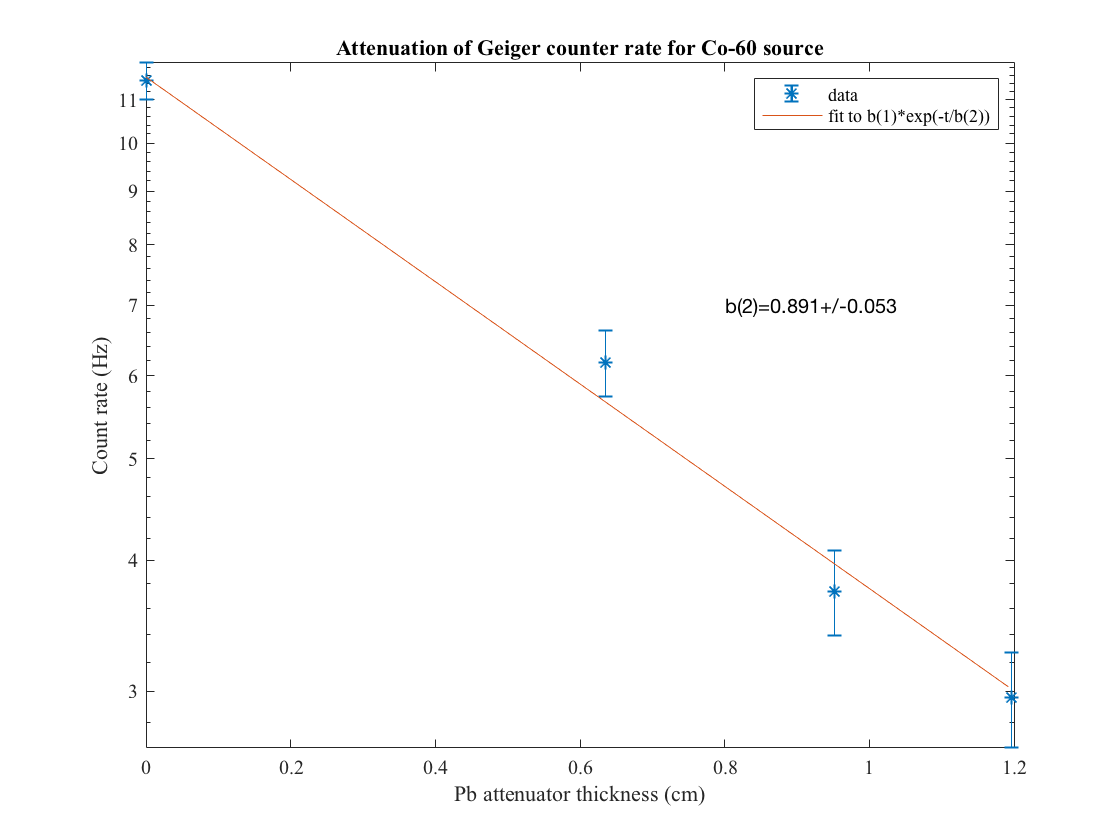

text(0.8,7,parameterstring)